Limpar 

close all
clear
clc

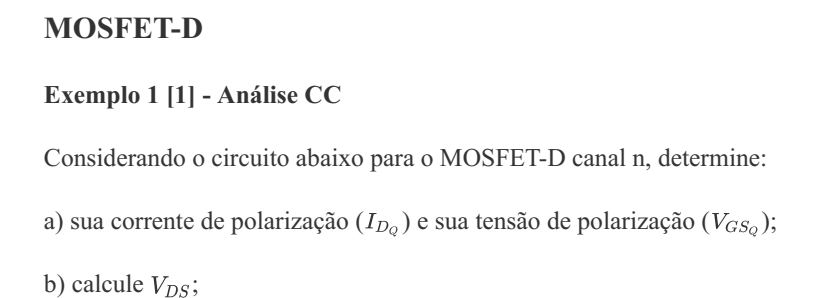

# Exemplo 1 apostila

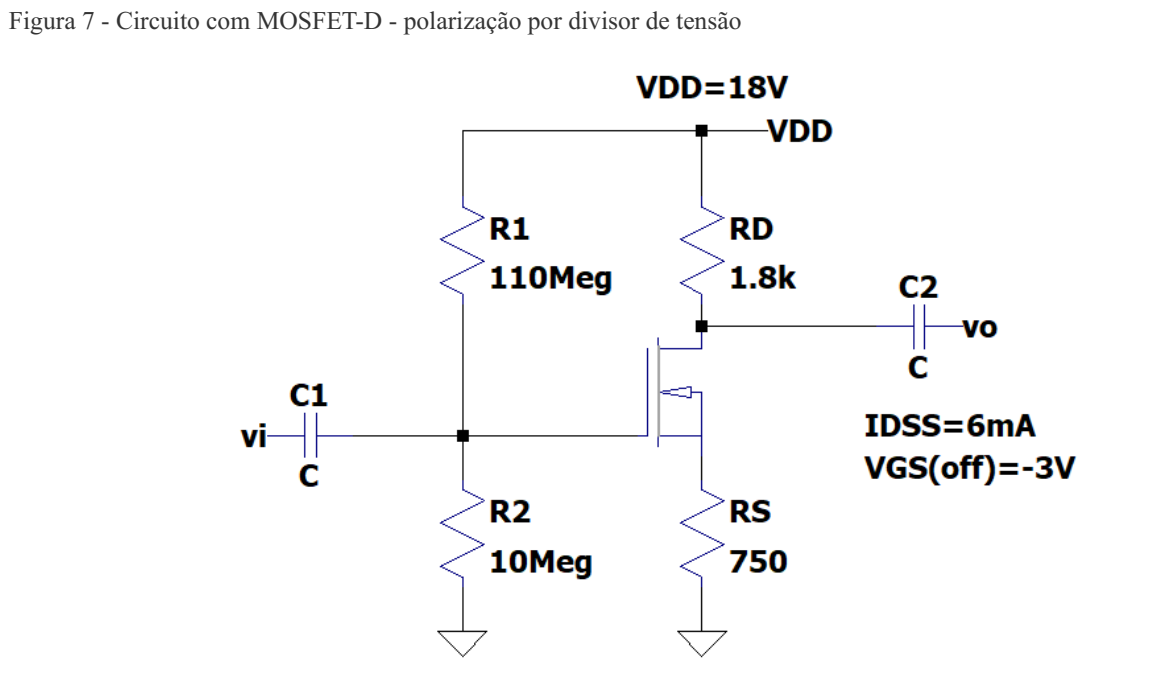

Fonte: PDF JFET e MOSFET do material de aula.

## Analise CC do circuito:

VDD=18;%(V) Regra estabelecida
IDSS = 6e-3;
VGSoff = -3;
R1 = 110e+6;
R2 = 10e+6;
RD = 1.8e+3;
RS = 750;


VG = (R2/(R2+R1))*VDD

VG = 1.5000

Considerando:

##             (1)

##                (2)

(2) em (1):

## a*ID^2 +b*ID+ C = 0 

*Lembrar esses equacionamentos podem ser feitos no symbolab

a = IDSS*RS^2

a = 3375

b = -(VGSoff^2)+2*IDSS*VGSoff*RS-2*IDSS*VG*RS

b = -49.5000

c = -2*IDSS*VGSoff*VG+IDSS*(VGSoff^2)+IDSS*(VG^2)

c = 0.1215

Resolvendo equação de Bhaskara temos nosso ID1 e ID2 

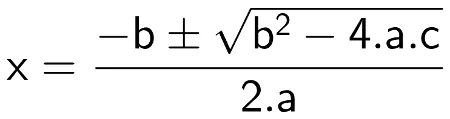

ID1 = (-b+(sqrt((b^2)-4*a*c)))/(2*a)

ID1 = 0.0115

ID2 = (-b-(sqrt((b^2)-4*a*c)))/(2*a)

ID2 = 0.0031

Aplicando na equação (2) obtemos o VGS das correntes e comparamos qual deles atende a nossa especificação:

VGS1 = VG - RS*ID1

VGS1 = -7.1623

VGS2 = VG - RS*ID2

VGS2 = -0.8377


if (VGS1<VGSoff && VGS2>VGSoff)  
    fprintf 'VGS1 Não atende'
    VGSQ = VGS2
    IDQ = ID2
end    

VGS1 Não atende

VGSQ = -0.8377

IDQ = 0.0031

if (VGS2<VGSoff && VGS1>VGSoff)
    fprintf 'VGS2 não atende'
        VGSQ = VGS1
        IDQ = ID1
end
if (VGS2<VGSoff && VGS1<VGSoff)
    fprintf 'nenhum atende recalcular'
end
if (VGS2>VGSoff && VGS1>VGSoff)
    fprintf 'Ambos atendem escolha qual VGS usar, padrão é VGS1'
    VGSQ = VGS1%Alterar para VGS2 caso queira e ambos possam ser utilizados
    IDQ = ID1 %Alterar para ID2 caso escolher VGS2
end

*o progrma ira partir automaticamente apos obter o valor, e usara VGSQ e IDQque atendam as condições para efetuar os calculos apartir de aqui!

b-)Calculo do VDS

VDS = VDD-(RD+RS)*IDQ

VDS = 10.0517